# 训练深度学习网络以对新图像进行分类

此示例使用：

- [Deep Learning Toolbox Model for GoogLeNet Network](https://ww2.mathworks.cn/help/deeplearning/ref/googlenet.html)

- [Deep Learning Toolbox](https://ww2.mathworks.cn/help/deeplearning/index.html)

此示例说明如何使用迁移学习来重新训练卷积神经网络以对新图像集进行分类。

预训练的图像分类网络已经对超过一百万个图像进行了训练，可以将图像分为 1000 个对象类别，例如键盘、咖啡杯、铅笔和多种动物。这些网络已基于大量图像学习了丰富的特征表示。网络以图像作为输入，然后输出图像中对象的标签以及每个对象类别的概率。

深度学习应用中常常用到迁移学习。您可以采用预训练的网络，基于它学习新任务。与使用随机初始化的权重从头训练网络相比，通过迁移学习来微调网络要更快更简单。您可以使用较少数量的训练图像快速地将已学习的特征迁移到新任务。

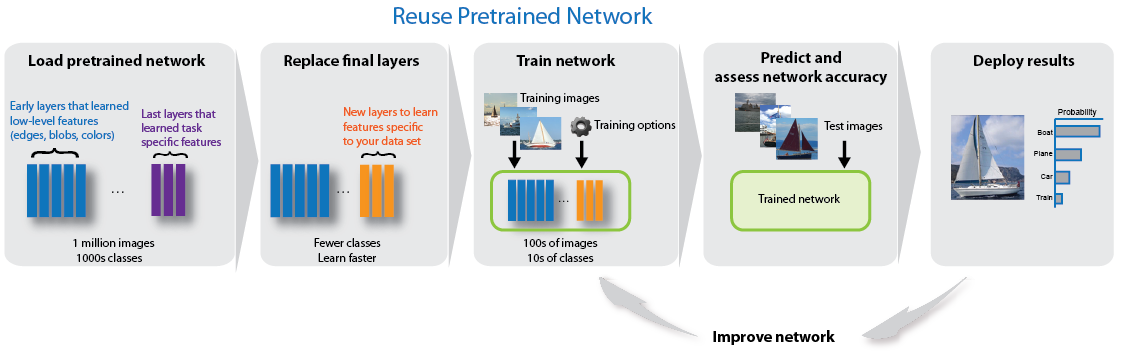

**加载数据**

解压缩新图像并加载这些图像作为图像数据存储。这个非常小的数据集只包含 75 个图像。将数据划分为训练数据集和验证数据集。将 70% 的图像用于训练，30% 的图像用于验证。

unzip('MerchData.zip');
imds = imageDatastore('MerchData', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames'); 
[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7);

**加载预训练网络**

加载预训练的 GoogLeNet 网络。如果未安装 Deep Learning Toolbox™ Model *for GoogLeNet Network* 支持包，则软件会提供下载链接。

要尝试不同的预训练网络，请在 MATLAB® 中打开此示例并选择其他网络。例如，您可以尝试 `squeezenet`，这是一个比 `googlenet` 还要快的网络。您可以使用其他预训练网络运行此示例。有关所有可用网络的列表，请参阅[加载预训练的神经网络](https://ww2.mathworks.cn/help/deeplearning/ug/pretrained-convolutional-neural-networks.html#mw_45a8c0b2-26fa-48e9-905a-a7ed7b87bfc8)。

net = googlenet;

使用 `analyzeNetwork` 可以交互可视方式呈现网络架构以及有关网络层的详细信息。

analyzeNetwork(net)

网络的 `Layers` 属性的第一个元素是图像输入层。对于 GoogLeNet 网络，该层需要大小为 224×224×3 的输入图像，其中 3 是颜色通道数。其他网络可能需要不同大小的输入图像。例如，Xception 网络需要大小为 299×299×3 的图像。

net.Layers(1)

ans =   ImageInputLayer - 属性:

                      Name: 'data'
                 InputSize: [224 224 3]
        SplitComplexInputs: 0

   超参数
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


inputSize = net.Layers(1).InputSize;

**替换最终层**

网络的卷积层会提取最后一个可学习层和最终分类层用来对输入图像进行分类的图像特征。GoogLeNet 中的 `'loss3-classifier'` 和 `'output'` 这两个层包含有关如何将网络提取的特征合并为类概率、损失值和预测标签的信息。要对预训练网络进行重新训练以对新图像进行分类，请将这两个层替换为适合新数据集的新层。

将经过训练的网络转换为层图。 

lgraph = layerGraph(net);

查找要替换的两个层的名称。您可以手动执行此操作，也可以使用支持函数 `findLayersToReplace` 自动查找这两个层。

[learnableLayer,classLayer] = findLayersToReplace(lgraph);
[learnableLayer,classLayer] 

ans =   具有以下层的 1×2 Layer 数组:

     1   'loss3-classifier'   全连接     1000 全连接层
     2   'output'             分类输出   crossentropyex: 具有 'tench' 和 999 个其他类

在大多数网络中，具有可学习权重的最后一层是全连接层。将此全连接层替换为新的全连接层，其中输出数量等于新数据集中类的数量（在此示例中为 5）。而在某些网络（如 SqueezeNet）中，最后一个可学习层是一个 1×1 卷积层。在这种情况下，请将该卷积层替换为新的卷积层，其中滤波器的数量等于类的数量。要使新层中的学习速度快于迁移的层，请增大该层的学习率因子。

如果 `A` 具有 `dataType` 指定的数据类型，`tf =` `isa``(`[`A`](https://ww2.mathworks.cn/help/matlab/ref/isa.html?searchHighlight=isa&s_tid=srchtitle_support_results_1_isa#mw_8bc7b96d-3c65-4642-9614-cb8f9593b20f)`,`[`dataType`](https://ww2.mathworks.cn/help/matlab/ref/isa.html?searchHighlight=isa&s_tid=srchtitle_support_results_1_isa#mw_0e9e39f7-a2c6-4979-91fe-87f370e64425)`)` 将返回 `1` (`true`)。否则，将返回 `0` (`false`)。输入参数 `A` 可以具有任何数据类型。

numClasses = numel(categories(imdsTrain.Labels));

if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end

lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);

分类层指定网络的输出类。将分类层替换为没有类标签的新分类层。`trainNetwork` 会在训练时自动设置层的输出类。

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

要检查新层是否正确连接，请绘制新的层图并放大网络的最后几层。

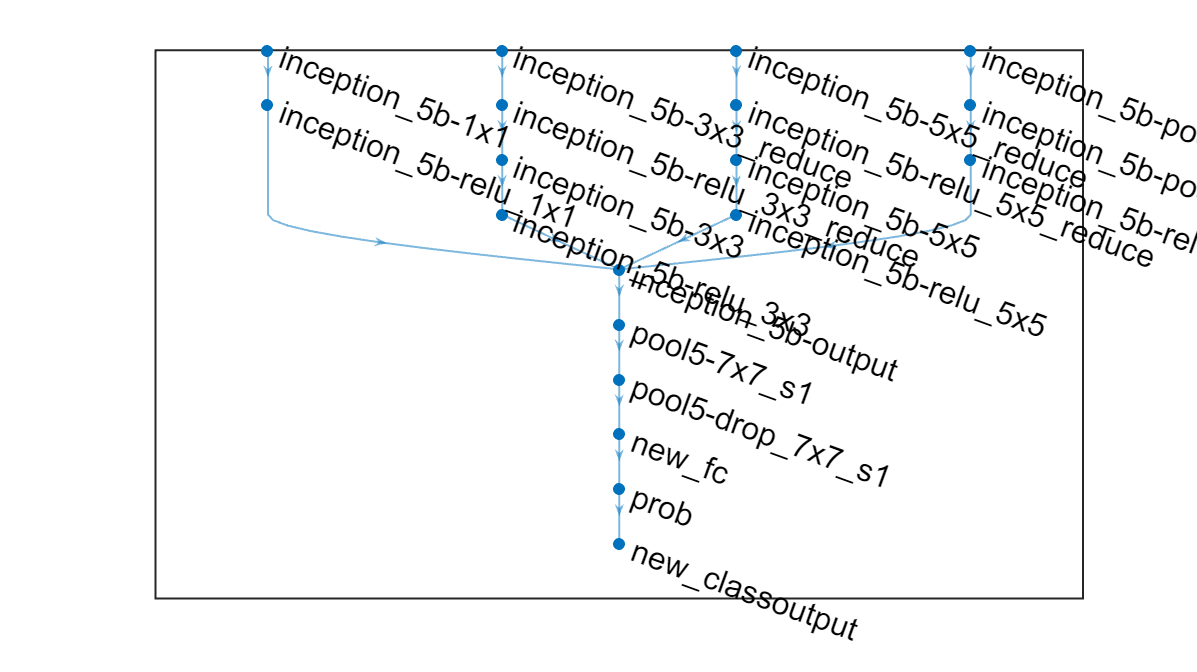

figure('Units','normalized','Position',[0.3 0.3 0.4 0.4]);
plot(lgraph)
ylim([0,10])

**冻结初始层**

现在，网络已准备好针对新的图像集进行重新训练。您也可以选择将较浅网络层的学习率设置为零，来“冻结”这些层的权重。在训练过程中，`trainNetwork` 不会更新已冻结层的参数。由于不需要计算已冻结层的梯度，因此冻结多个初始层的权重可以显著加快网络训练速度。如果新数据集很小，冻结较浅的网络层还可以防止这些层对新数据集过拟合。

提取层图的层和连接，并选择要冻结的层。在 GoogLeNet 中，前 10 个层构成了网络的初始“主干”。使用辅助函数 `freezeWeights` 将前 10 个层的学习率设置为零。使用支持函数 `createLgraphUsingConnections` 以原始顺序重新连接所有层。新的层图包含相同的层，但较浅层的学习率设置为零。

layers = lgraph.Layers;
connections = lgraph.Connections;
layers(1:10) = freezeWeights(layers(1:10));
lgraph = createLgraphUsingConnections(layers,connections);

**训练网络**

网络要求输入图像的大小为 224×224×3，但图像数据存储中的图像具有不同大小。使用增强的图像数据存储可自动调整训练图像的大小。指定要对训练图像执行的附加增强操作：沿垂直轴随机翻转训练图像，以及在水平和垂直方向上随机平移训练图像最多 30 个像素并将训练图像缩放最多 10%。数据增强有助于防止网络过拟合和记忆训练图像的具体细节。

pixelRange = [-30 30];
scaleRange = [0.9 1.1];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange);
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    'DataAugmentation',imageAugmenter);

要在不执行进一步数据增强的情况下自动调整验证图像的大小，请使用增强的图像数据存储，而不指定任何其他预处理操作。

augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

指定训练选项。将 `InitialLearnRate` 设置为较小的值以减慢尚未冻结的迁移层中的学习速度。在上一步中，您增大了最后一个可学习层的学习率因子，以加快新的最终层中的学习速度。这种学习率设置组合会加快新层中的学习速度，减慢中间层中的学习速度，停止较浅的冻结层中的学习。

指定要训练的轮数。执行迁移学习时，所需的训练轮数相对较少。一轮训练是对整个训练数据集的一个完整训练周期。指定小批量大小和验证数据。每轮计算一次验证准确度。

miniBatchSize = 10;
valFrequency = floor(numel(augimdsTrain.Files)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',3e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',valFrequency, ...
    'Verbose',false, ...
    'Plots','training-progress');

使用训练数据训练网络。默认情况下，`trainNetwork` 使用 GPU（如果有）。这需要 Parallel Computing Toolbox™ 和支持的 GPU 设备。有关受支持设备的信息，请参阅[GPU Computing Requirements](https://ww2.mathworks.cn/help/parallel-computing/gpu-computing-requirements.html) (Parallel Computing Toolbox)。否则，`trainNetwork` 将使用 CPU。您还可以使用 `trainingOptions` 的 `'ExecutionEnvironment'` 名称-值对组参数指定执行环境。由于数据集很小，因此训练很快。

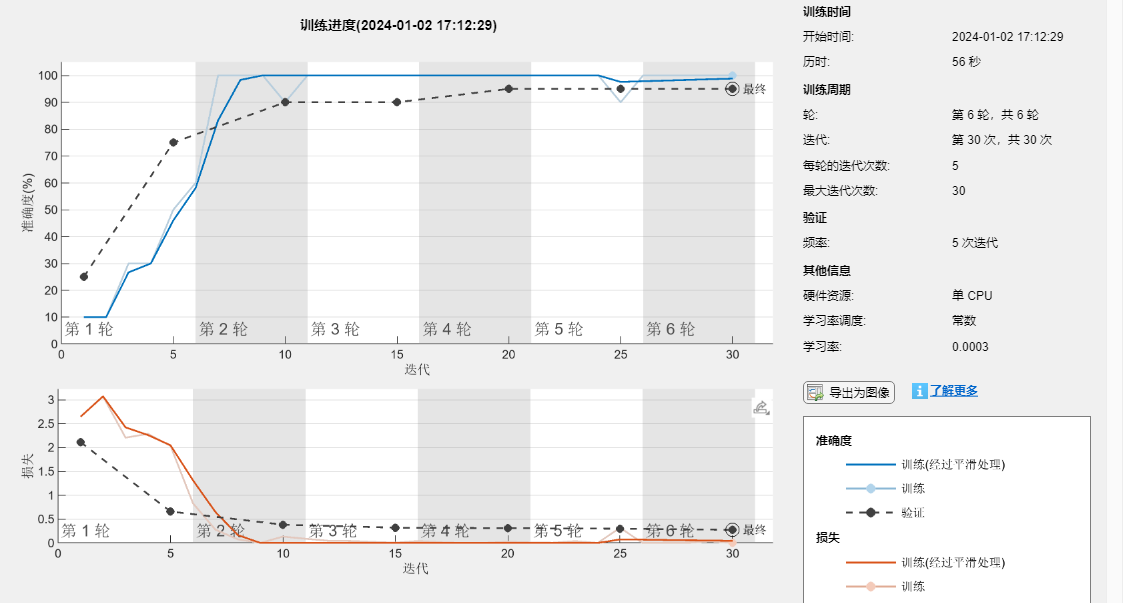

net = trainNetwork(augimdsTrain,lgraph,options);

**对验证图像进行分类**

使用经过微调的网络对验证图像进行分类，并计算分类准确度。

[YPred,probs] = classify(net,augimdsValidation);
accuracy = mean(YPred == imdsValidation.Labels)

accuracy = 0.9500

显示四个示例验证图像及预测的标签，以及具有这些标签的图像的预测概率。

`p =` `randperm``(`[`n`](https://ww2.mathworks.cn/help/matlab/ref/randperm.html?searchHighlight=randperm&s_tid=srchtitle_support_results_1_randperm#mw_09362558-0841-4b6e-9ea2-72634a543286)`,`[`k`](https://ww2.mathworks.cn/help/matlab/ref/randperm.html?searchHighlight=randperm&s_tid=srchtitle_support_results_1_randperm#mw_2a6fc12d-4a79-4bf4-b4b2-cb0278a3a8fe)`)` 返回行向量，其中包含在 1 到 `n` 之间随机选择的 `k` 个唯一整数。

`n =` `numel``(`[`A`](https://ww2.mathworks.cn/help/matlab/ref/double.numel.html?searchHighlight=numel&s_tid=srchtitle_support_results_1_numel#btl24wx-1-A)`)` 返回数组 `A` 中的元素数目 `n` 等同于 `prod(size(A))`。

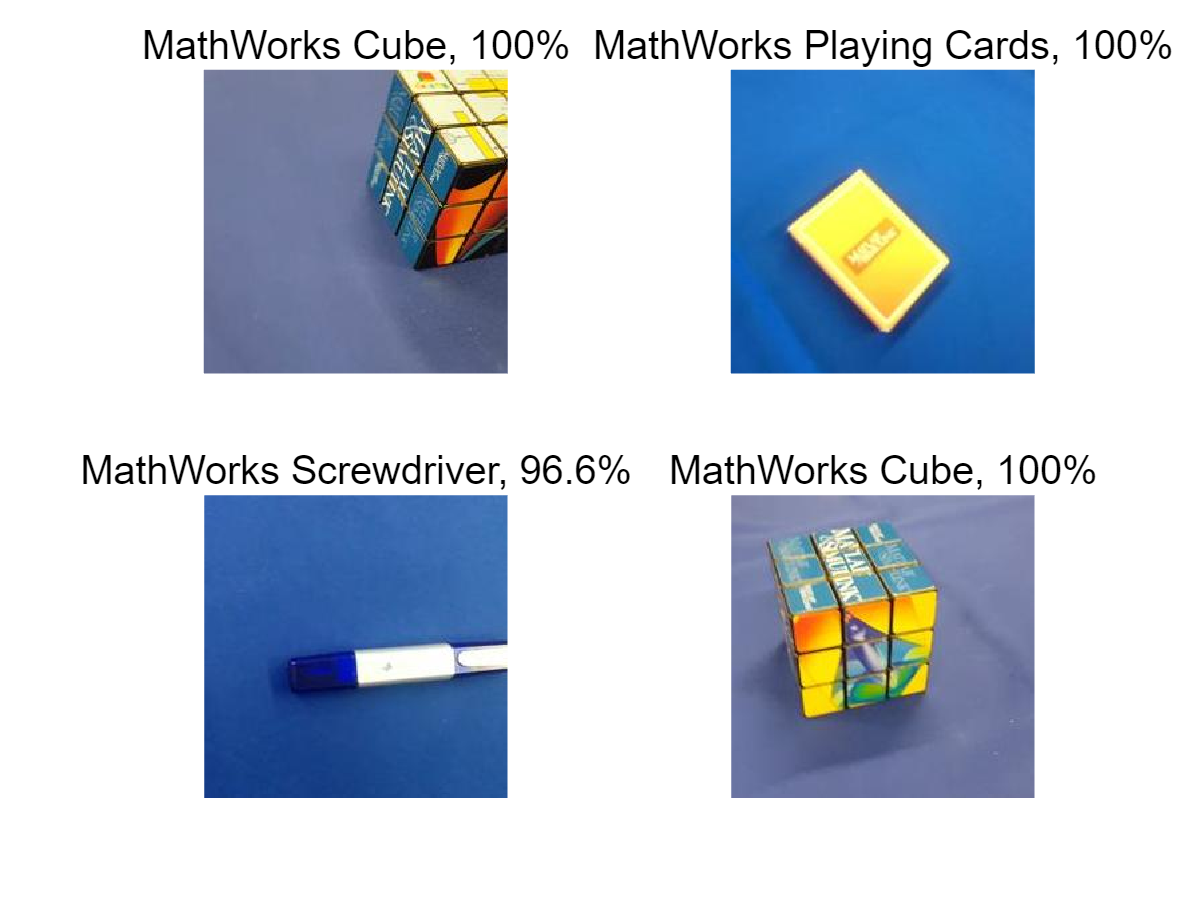

idx = randperm(numel(imdsValidation.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label) + ", " + num2str(100*max(probs(idx(i),:)),3) + "%");
end